plot(TURQUOISEvoltage,TURQUOISEcurrent,'.')
hold on

%%CREATING ERRORBARS

xpos=0.001.*[1 1 1 1 1 1 1 1 1 1];
xneg=xpos;
ypos=(0.2e-13).*[1 1 1 1 1 1 1 1 1 1];
yneg=ypos;
errorbar(TURQUOISEvoltage,TURQUOISEcurrent,yneg,ypos,xneg,xpos,'o')

%%NEGATIVE DATA
%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =      -2e-13  (-1.667e-12, 1.267e-12)
  %     p2 =   6.333e-14  (-5.996e-13, 7.263e-13)

%Goodness of fit:
 % SSE: 6.667e-29
  %R-square: 0.75
  %Adjusted R-square: 0.5
  %RMSE: 8.165e-15
   p1 =      -2e-13 ;

p1 = -2.0000e-13

   p2 =   6.333e-14;

p2 = 6.3330e-14

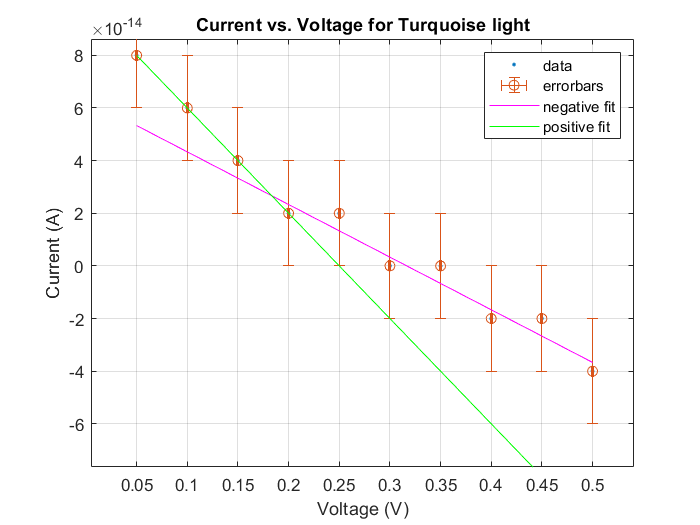

   f = p1.*TURQUOISEvoltage+ p2;
   plot(TURQUOISEvoltage,f,'m')
   
   %%POSITIVE DATA
%   Linear model Poly1:
 %    f(x) = p3*x + p4
%Coefficients (with 95% confidence bounds):
 %      p3 =      -4e-13  (-4e-13, -4e-13)
  %     p4 =       1e-13  (1e-13, 1e-13)

%Goodness of fit:
 % SSE: 3.345e-57
  %R-square: 1
  %Adjusted R-square: 1
  %RMSE: 4.09e-29
   p3 =      -4e-13;
  p4 =       1e-13;
  g=p3.*TURQUOISEvoltage + p4;
  plot(TURQUOISEvoltage,g,'g')


legend({'data','errorbars','negative fit','positive fit'})
title('Current vs. Voltage for Turquoise light')
xlabel('Voltage (V)')
ylabel('Current (A)')
grid on

xlim([0.005 0.541])
ylim([-0.000000000000076 0.000000000000086])